# Rigid body rotational motion

true dataの生成とかに．

clc
clear
close all

MOI = diag([10, 15, 20]);

## state variables 


$${\bf x}= [q_1, q_2, q_3, q_4, \omega_x, \omega_y, \omega_z]^T$$


ini = [0.0 
    0.0    
    0.0
    1.0
    deg2rad(10.0)    % wx, angular rate, rad/s
    deg2rad(5.0)
    deg2rad(-5.0)];

tspan = 0:1:60*30;
opts = odeset('RelTol',1e-8, 'AbsTol',1e-8);
[t_, x_] = ode45(@(t,x)eulerEom(t,x, MOI), tspan, ini, opts);


## data handling

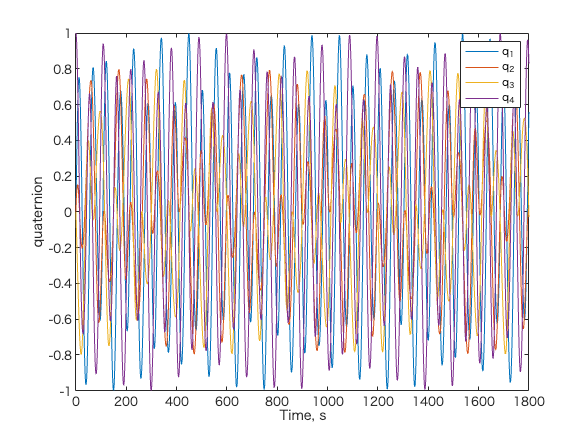

q1 = x_(:,1);
q2 = x_(:,2);
q3 = x_(:,3);
q4 = x_(:,4);
q = [q1, q2, q3, q4];

wx = x_(:,5);
wy = x_(:,6);
wz = x_(:,7);
w = [wx, wy, wz];

figure
plot(t_, q1, t_, q2, t_, q3, t_, q4);
legend('q_1', 'q_2', 'q_3', 'q_4');
xlabel('Time, s'), ylabel('quaternion')

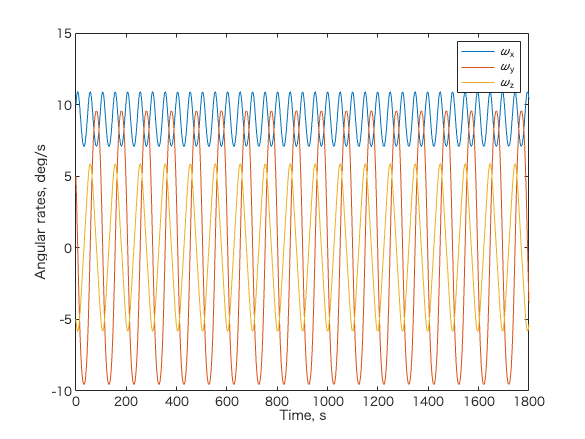


figure
plot(t_, rad2deg(wx), t_, rad2deg(wy), t_, rad2deg(wz));
legend('\omega_x', '\omega_y', '\omega_z');
xlabel('Time, s'), ylabel('Angular rates, deg/s')

## save data

save('qw.mat', 't_', 'q', 'w')